# Recycling Analysis Demo

Use RecyclingAnalysis function to obtain the potencial saving cost of waste recycling

#### Read the Data Model

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Set the parameters and get the RecyclingAnalysis results

WasteFlows=convertCharsToStrings(data.WasteData.Flows);
param.WasteFlow=convertStringsToChars(WasteFlows(1));
States=convertCharsToStrings(data.States);
param.State=convertStringsToChars(States(1));
Samples=convertCharsToStrings(data.ResourceSamples);
param.ResourceSample=convertStringsToChars(Samples(2));
res=RecyclingAnalysis(data,param);

#### Show the Results

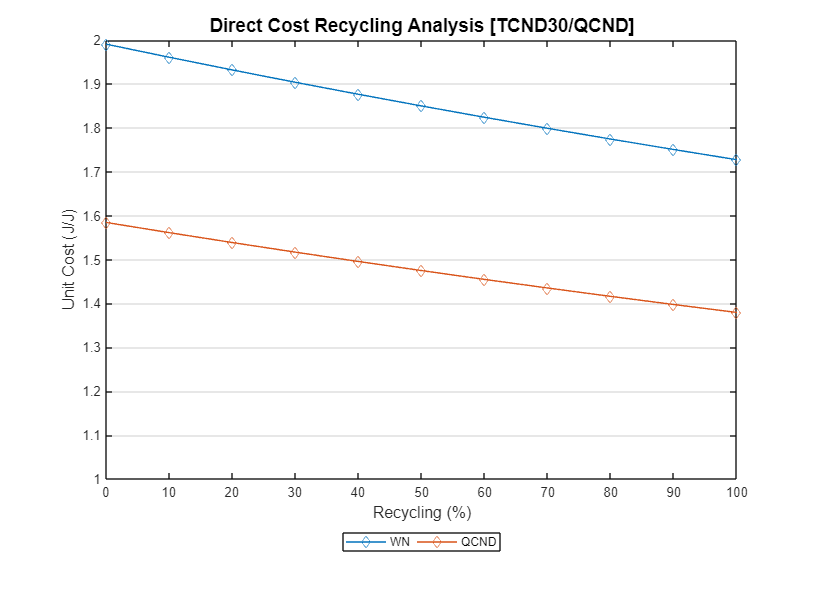

graphRecycling(res,cType.Tables.WASTE_RECYCLING_DIRECT);

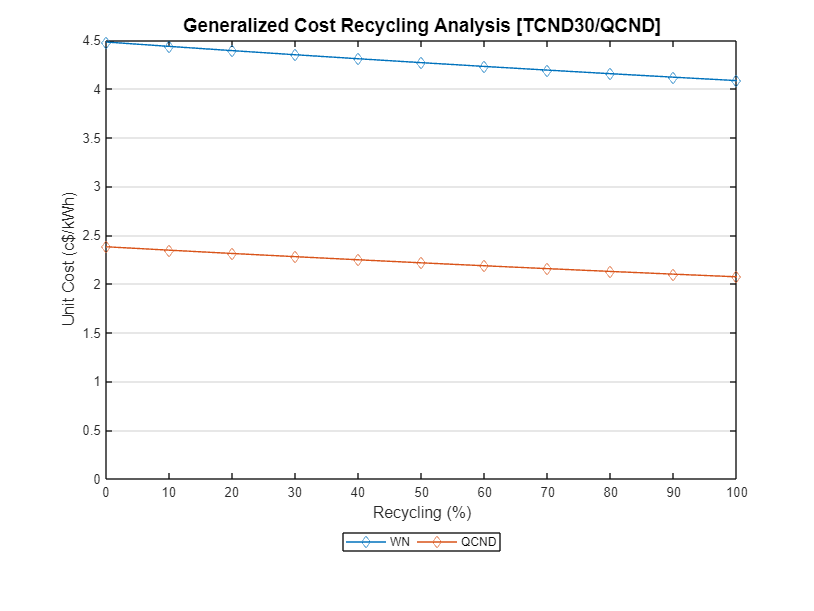

graphRecycling(res,cType.Tables.WASTE_RECYCLING_GENERAL);

printResults(res);

Direct Cost Recycling Analysis (J/J)

 Recycle (%)          WN       QCND
------------------------------------
      0           1.9906     1.5844
     10           1.9608     1.5612
     20           1.9318     1.5387
     30           1.9037     1.5168
     40           1.8764     1.4955
     50           1.8498     1.4748
     60           1.8239     1.4546
     70           1.7988     1.4350
     80           1.7743     1.4160
     90           1.7505     1.3974
    100           1.7272     1.3793


Generalized Cost Recycling Analysis (c$/kWh)

 Recycle (%)          WN       QCND
------------------------------------
      0           4.4793     2.3806
     10           4.4346     2.3457
     20           4.3911     2.3119
     30           4.3488     2.2790
     40           4.3077     2.2470
     50           4.2678     2.2159
     60           4.2290     2.1856
     70           4.1912     2.1562
     80           4.1544     2.1275
     90           4.1186     2.0996
    100     